## Part 3: Image Convolution Filtering Operation

% padarray() for zero padding image? 
% ref 1: https://au.mathworks.com/help/images/ref/padarray.html
% ref 2: https://au.mathworks.com/matlabcentral/answers/612661-how-can-i-use-zero-padding-in-an-image 
% ref 3: https://au.mathworks.com/matlabcentral/answers/469306-zero-pad-to-resize-an-image
% define the kernels
box_3x3 = ones(3, 3) / 9;
box_5x5 = ones(5, 5) / 25;
% ref: https://au.mathworks.com/help/matlab/math/creating-and-concatenating-matrices.html
gaussian_5x5 = [1 4 6 4 1;
               4 16 24 16 4;
               6 24 36 24 6; 
               4 16 24 16 4;
               1 4 6 4 1] / 256; % should be a 5x5 matrix
% input image
degraded_a = imread("Degraded_A.tif");
% standard built in matlab convolution
A = imfilter(degraded_a, box_3x3);
B = imfilter(degraded_a, box_5x5);
C = imfilter(degraded_a, gaussian_5x5);
% ref: https://www.youtube.com/watch?v=hMHJitFkiQ8

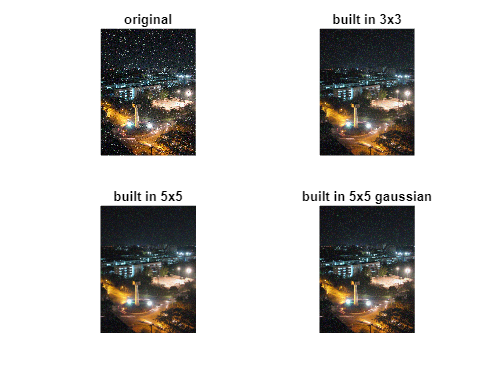

% plot to compare the built in function - imfilter() function
figure;
subplot(221); imshow(degraded_a); title('original');
subplot(222); imshow(A); title('built in 3x3');
subplot(223); imshow(B); title('built in 5x5');
subplot(224); imshow(C); title('built in 5x5 gaussian');

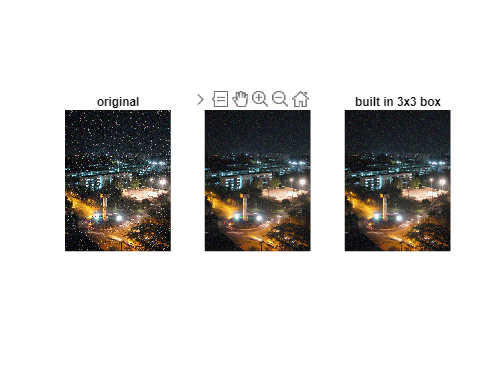

% switch to double instead of uint8
double_a = double(degraded_a);
% ref 4: https://au.mathworks.com/matlabcentral/answers/450878-i-want-create-a-convolution-filter-for-rgb-images

% Zeropad images
function zero_pad = zero_pad_images(images, pad_height, pad_width)
    [original_height, original_width, num_channels] = size(images);

    % new dimension
    new_height = original_height + 2 * pad_height; % add top and bottom
    new_width = original_width + 2 * pad_width;
    % create new zero matrix with 
    zero_pad = zeros(new_height, new_width, num_channels);
    % place the original image in the center, on top of the zero matrix
    zero_pad(pad_height + 1: pad_height + original_height, ...
            pad_width + 1 : pad_width + original_width, :) = images;
end

% The (Actual) Convolution Function
function output = convolution(images, kernels)
    % rows and columns are taken from the size of the image rows and columns    
    [rows, cols, num_channels] = size(images);
    [kernel_rows, kernel_cols] = size(kernels);
        
    % padding size is determined based on the kernel 
    pad_rows = floor(kernel_rows / 2);
    pad_cols = floor(kernel_cols / 2);
        
    % zero padding the image
    zero_pad = zero_pad_images(images, pad_rows, pad_cols);
        
    % output image
    output = zeros(rows, cols, num_channels);
        
    % loop the convolution
    for channel = 1:num_channels
        for i = 1:rows
            for j = 1:cols
                image_roi = zero_pad(i:i + kernel_rows - 1, j:j + kernel_cols - 1, channel);
                output(i,j, channel) = sum(sum(image_roi .* kernels));
            end
        end
    end
end

% Function to apply the custom convolution on the images RGB channels
% Modified after observing the final output
function final_output = apply_convolution(images, kernels)
    final_output = convolution(images, kernels);
    final_output = uint8(final_output);
end

% apply the custom convolution
a_3x3 = apply_convolution(double_a, box_3x3);
a_5x5 = apply_convolution(double_a, box_5x5);
agaussian_5x5 = apply_convolution(double_a, gaussian_5x5);

% display the image
figure;
subplot(131), imshow(degraded_a), title('original');
subplot(132), imshow(a_3x3), title('custom 3x3 box');
subplot(133); imshow(A);title('built in 3x3 box');

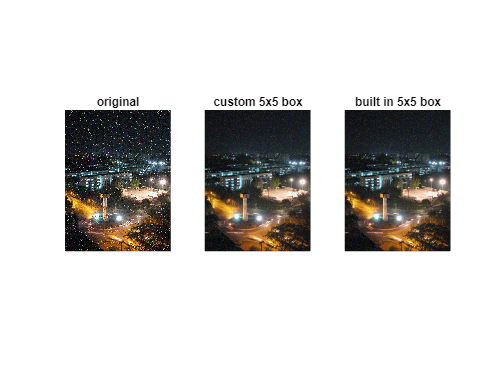

figure;
subplot(131); imshow(degraded_a);title('original');
subplot(132); imshow(a_5x5);title('custom 5x5 box');
subplot(133); imshow(B); title('built in 5x5 box');

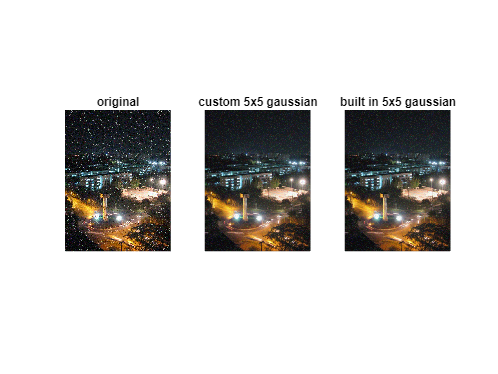

figure;
subplot(131); imshow(degraded_a);title('original');
subplot(132); imshow(agaussian_5x5);title('custom 5x5 gaussian');
subplot(133); imshow(C);title('built in 5x5 gaussian');

## Part 4: 1D Filtering

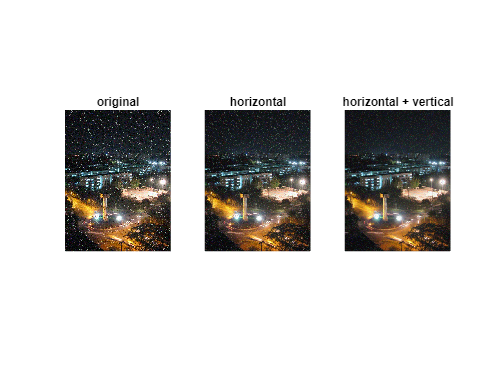

degraded_a = imread("Degraded_A.tif");
% switch to double instead of uint8
double_a = double(degraded_a);
% initialize filters
horizontal = [1 4 6 4 1] / 16;
vertical = horizontal';
% apply the filter to the image
D = apply_convolution(double_a, horizontal);
E = apply_convolution(D, vertical); 
% plot the images for comparison
figure;
subplot(131); imshow(degraded_a); title('original');
subplot(132); imshow(D); title('horizontal');
subplot(133); imshow(E); title('horizontal + vertical');